clc;
clear;

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% 比较 Nonapp, app, Combine CIO, BESTAnP, CRLB
% 在不同点数下的RMSE
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% 设置环境变量，允许 OpenMP 运行时重复加载
setenv('KMP_DUPLICATE_LIB_OK', 'TRUE');  %防止报错

% 将此更改为你的脚本目录
py_path = 'C:\Users\Lenovo\Desktop\Matab Code\Experiments\test_numberpoint_influence'; 



%%%%%%%%%%%%%%%%%%%%%%%%%%%
% 数据准备
%%%%%%%%%%%%%%%%%%%%%%%%%%%
%旋转矩阵
% R_true= [0.4032    0.6640   0.6297;
%        0.5090   0.4092    -0.7573;
%       0.7605    -0.6258    0.1730];

R_true=[0.689673028293550	0.423447870703166	0.587403621746887
        0.176155229057263	0.688715772969376	-0.703306419236294
        -0.702367745073895	0.588525687510876	0.400396136119796];

%平移矢量
t_true = [2;3;4];
t_s_true = -R_true'*t_true;



% 
num = [3,5,7,30,90,270,1000];
% 
% num = [10,30,90];

for n = 1:length(num)
    n
    phi_max = 10*pi/180;
%     % 生成俯仰角 [-10°, 10°] 转换为弧度
%     elevation_angles = -phi_max + 2*phi_max*rand(num(1,n), 1);
    % 生成俯仰角 [-10°, 10°] 转换为弧度
    elevation_angles = deg2rad(-10 + 20*rand(1, num(1,n)));
    % 生成方位角 [-30°, 30°]
    azimuth_angles = (-pi/6) + (pi/3) * rand(1, num(1,n));
    % 生成距离 [0, 6] 米
    d_true = 6 * rand(1, num(1,n));
    
    p_s = [];
    % 生成 p_s
    p_s(1,:)= (d_true .* cos(elevation_angles) .* cos(azimuth_angles));
    p_s(2,:)= (d_true .* cos(elevation_angles) .* sin(azimuth_angles));
    p_s(3,:)= (d_true .* sin(elevation_angles))';
    
    p_si = [];
    % 生成 p_si
    p_si(1,:)= d_true .* cos(azimuth_angles);
    p_si(2,:)= d_true .* sin(azimuth_angles);
    
    % 生成 p_w
    p_w = R_true*p_s+t_true;

n = 1

n = 2

n = 3

n = 4

n = 5

n = 6

n = 7

    
    
    % M = 1;
    M = 1000;


    % Wang's algorithm initial parameters
    error_t_App = 0;
    error_R_App = 0;

    error_t_combine_CIO = 0;
    error_R_combine_CIO = 0;
    

    error_t_Nonapp = 0;
    error_R_Nonapp = 0;

    % Our algorithm initial parameters
    error_t_BESTAnP = 0;
    error_R_BESTAnP = 0;

    error_t_initial = 0;
    error_R_initial = 0;

    error_t_BESTAnP_CIO = 0;
    error_R_BESTAnP_CIO = 0;
        
    
    for j = 1:M
        % --------------------
        % 噪声数据
        % --------------------
        % 生成噪声数据
        temp_std_noise = 0.001;
        stdVar_noise_d = temp_std_noise;
        stdVar_noise_theta = temp_std_noise;
        
        d_noise = d_true + stdVar_noise_d*randn(1, num(1,n));
        
        noise_on_theta = stdVar_noise_theta*randn(1, num(1,n));

        %----------------------------------
        % 生成噪声数据 加在tan上、
        tan_theta = tan(azimuth_angles);
        tan_theta_noise_ori = tan_theta + noise_on_theta;
        
        theta_noise_tan_ori= atan(tan_theta_noise_ori);
        
        cos_theta_noise_tan = cos(theta_noise_tan_ori);
        sin_theta_noise_tan = sin(theta_noise_tan_ori);
        p_si_noise = [d_noise.*cos_theta_noise_tan;d_noise.*sin_theta_noise_tan];


        
%         Var_noise_base =0.0001;
%         % 距离信息上添加噪声
%         Var_noise_d =  Var_noise_base;  
%         d_noise = d_true + (Var_noise_d)* randn(1,num(1,n));
%           
%         % 方位角信息上添加噪声
%         Var_noise_theta =  Var_noise_base;
%         tan_theta_noise = tan_theta_ture +(Var_noise_theta)* randn(1,num(1,n));
% 
%         theta_noise= atan(tan_theta_noise);
%         cos_theta_noise = cos(theta_noise);
%         sin_theta_noise = sin(theta_noise);
%         p_si_noise = [d_noise.*cos_theta_noise;d_noise.*sin_theta_noise];
        

         % Wang's algorithm
        if num(n)>=3
            [R_app,t_app]=App_Algorithm(p_w,p_si_noise,phi_max,py_path);
            % [R_app,t_app]=App_Algorithm(p_w,p_si_noise,phi_max,py_path);
            s_app = rotm2eul(R_app*R_true','XYZ');
            error_R_App = error_R_App + norm(s_app)^2;

            error_t_App = error_t_App + norm(t_app-t_true)^2;

            if num(n)>=5
                 % My algorithm
                [R_BESTAnP,t_BESTAnP]=BESTAnP(p_w,p_si_noise);

                [R_initial,t_initial]=BESTAnP_initial_solution(p_w,p_si_noise);

                result_CIO = py.CIO.CIO(R_BESTAnP', -R_BESTAnP'*t_BESTAnP, p_w, p_si_noise, phi_max);

                R_CIO = double(result_CIO{1});
                t_CIO  = double(result_CIO{2})';

                R_BESTAnP_CIO  = R_CIO';
                t_BESTAnP_CIO  = -R_CIO'*t_CIO;

                s_BESTAnP = rotm2eul(R_true'*R_BESTAnP,'XYZ');

                s_initial = rotm2eul(R_initial*R_true','XYZ');
                s_initial_CIO = rotm2eul(R_BESTAnP_CIO*R_true','XYZ');

                error_R_BESTAnP = error_R_BESTAnP + norm(s_BESTAnP)^2;

                error_R_initial = error_R_initial + norm(s_initial)^2;
                error_R_BESTAnP_CIO = error_R_BESTAnP_CIO + norm(s_initial_CIO)^2;

                error_t_BESTAnP = error_t_BESTAnP + norm(t_BESTAnP-t_true)^2;

                error_t_initial = error_t_initial + norm(t_initial-t_true)^2;
                error_t_BESTAnP_CIO = error_t_BESTAnP_CIO + norm(t_BESTAnP_CIO-t_true)^2;

                if num(n)>=7
                    [R_Nonapp,t_Nonapp]=Nonapp_Algorithm(p_w,p_si_noise,phi_max,R_true,py_path);

                    [R_combine_CIO,t_combine_CIO] = Combine_CIO(p_w,p_si_noise,phi_max,R_true,py_path);

                    s_combine_CIO =  rotm2eul(R_combine_CIO*R_true','XYZ');

                    s_Nonapp =  rotm2eul(R_Nonapp*R_true','XYZ');

                     error_R_combine_CIO = error_R_combine_CIO + norm(s_combine_CIO)^2;

                    error_R_Nonapp = error_R_Nonapp + norm(s_Nonapp)^2;

                    error_t_combine_CIO = error_t_combine_CIO + norm(t_combine_CIO-t_true)^2;

                    error_t_Nonapp = error_t_Nonapp + norm(t_Nonapp-t_true)^2;
                end

            end



        end
   
  

        
    end

    [crlb_R,crlb_t] = Calculate_CRLB(p_w,R_true,t_true,stdVar_noise_d,stdVar_noise_theta);


    CRLB_t_x(n,:) = sqrt(crlb_t);
    CRLB_R_x(n,:) = sqrt(crlb_R);

    % Wang's algorithm
    Error_t_App(n,:) = sqrt(error_t_App/M);
    Error_R_App(n,:) = sqrt(error_R_App/M);

    Error_t_combine_CIO(n,:) = sqrt(error_t_combine_CIO/M);
    Error_R_combine_CIO(n,:) = sqrt(error_R_combine_CIO/M);


    Error_t_Nonapp(n,:) = sqrt(error_t_Nonapp/M);
    Error_R_Nonapp(n,:) = sqrt(error_R_Nonapp/M);



     % my algorithm
    Error_t_BESTAnP(n,:) = sqrt(error_t_BESTAnP/M);
    Error_R_BESTAnP(n,:) = sqrt(error_R_BESTAnP/M);

    Error_t_initial(n,:) = sqrt(error_t_initial/M);
    Error_R_initial(n,:) = sqrt(error_R_initial/M);

    Error_t_BESTAnP_CIO(n,:) = sqrt(error_t_BESTAnP_CIO/M);
    Error_R_BESTAnP_CIO(n,:) = sqrt(error_R_BESTAnP_CIO/M);

end

% num = [3,5,7,30,90,270,1000];

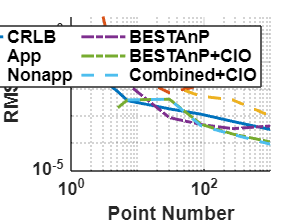

figure
grid on 
hold on;

loglog(num,CRLB_t_x,'LineWidth', 2,  'MarkerSize', 5);



% loglog(num,Error_t_initial,'--','LineWidth', 2, 'MarkerSize', 5);

loglog(num,Error_t_App,'--','LineWidth', 2, 'MarkerSize', 5);

loglog(num,Error_t_Nonapp,'--','LineWidth', 2, 'MarkerSize', 5);
% loglog(num,Error_t_Nonapp_CIO,'-.','LineWidth', 2, 'MarkerSize', 5);

loglog(num,Error_t_BESTAnP,'-.','LineWidth', 2,  'MarkerSize', 5);

loglog(num,Error_t_BESTAnP_CIO,'-.','LineWidth', 2, 'MarkerSize', 5);

loglog(num,Error_t_combine_CIO,'--','LineWidth', 2, 'MarkerSize', 5);









% legend('CRLB','BESTAnP','App','Non-app','Combine+CIO','FontSize', 12, 'FontWeight', 'bold');
% legend('CRLB','Initial CEs','App','Nonapp','BESTAnP(GN)','BESTAnP(CIO)','Combined+CIO','FontSize', 12, 'FontWeight', 'bold','NumColumns', 2);
% legend('CRLB','Initial CEs','App','Nonapp','BESTAnP','BESTAnP+CIO','Combined+CIO','FontSize', 12, 'FontWeight', 'bold','NumColumns', 2);
legend('CRLB','App','Nonapp','BESTAnP','BESTAnP+CIO','Combined+CIO','FontSize', 12, 'FontWeight', 'bold','NumColumns', 2);


xlabel('Point Number','FontSize', 12, 'FontWeight', 'bold');
ylabel('RMSE_t','FontSize', 12, 'FontWeight', 'bold');
set(gca, 'XScale', 'log', 'YScale', 'log','FontSize', 12, 'FontWeight', 'bold');

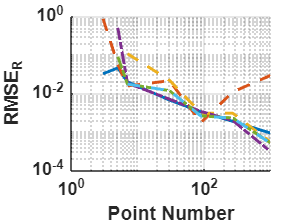

figure
grid on 
hold on;

loglog(num,CRLB_R_x,'LineWidth', 2,  'MarkerSize', 5);

% loglog(num,Error_R_initial,'--','LineWidth', 2, 'MarkerSize', 5);

loglog(num,Error_R_App,'--','LineWidth', 2, 'MarkerSize', 5);

loglog(num,Error_R_Nonapp,'--','LineWidth', 2, 'MarkerSize', 5);


loglog(num,Error_R_BESTAnP,'-.','LineWidth', 2,  'MarkerSize', 5);
loglog(num,Error_R_BESTAnP_CIO,'-.','LineWidth', 2, 'MarkerSize', 5);

loglog(num,Error_R_combine_CIO,'--','LineWidth', 2, 'MarkerSize', 5);









% legend('CRLB','BESTAnP','App','Non-app','Combine+CIO','FontSize', 12, 'FontWeight', 'bold');

% legend('CRLB','Initial CEs','App','Nonapp','BESTAnP(GN)','BESTAnP(CIO)','Combined+CIO','FontSize', 12, 'FontWeight', 'bold','NumColumns', 2);
% legend('CRLB','App','Nonapp','BESTAnP','BESTAnP+CIO','Combined+CIO','FontSize', 12, 'FontWeight', 'bold','NumColumns', 2);

xlabel('Point Number','FontSize', 12, 'FontWeight', 'bold');
ylabel('RMSE_R','FontSize', 12, 'FontWeight', 'bold');
set(gca, 'XScale', 'log', 'YScale', 'log','FontSize', 12, 'FontWeight', 'bold');

% figure
% grid on 
% hold on;
% 
% 
% loglog(num,Error_t_BESTAnP,'--','LineWidth', 2,  'MarkerSize', 5);
% 
% loglog(num,CRLB_t_x,'LineWidth', 2,  'MarkerSize', 5);
% 
% loglog(num,Error_R_BESTAnP,'--','LineWidth', 2,  'MarkerSize', 5);
% 
% loglog(num,CRLB_R_x,'LineWidth', 2,  'MarkerSize', 5);
% 
% % loglog(num,CRLB_t_TOA,'LineWidth', 2,  'MarkerSize', 5);
% 
% legend('error t','CRLB t ','error R','CRLB R ','FontSize', 12, 'FontWeight', 'bold');
% 
% xlabel('Point Number','FontSize', 12, 'FontWeight', 'bold');
% ylabel('RMSE_t','FontSize', 12, 'FontWeight', 'bold');
% set(gca, 'XScale', 'log', 'YScale', 'log','FontSize', 12, 'FontWeight', 'bold');